# 숙제#3: 궤도역학

**[2026-봄] 인공위성시스템(ASE4080), 인하대학교 항공우주공학과**

**목성훈(shmok@inha.ac.kr)**

% 초기화
clear all; 
close all;
clc;
format long

% 파라미터
mu = 398600;        % [km3/s2] Earth gravitational constant
R = 6400;           % [km] Earth radius

### 1. 운용고도 vs 공전속도, 공전주기 [20점]

고도에 따른 공전속도와 공전주기를 구한다. 고도는 500 km 부터 36000 km 까지 100 km 격자로 나누어 사용하시오. 궤도는 원궤도로 가정한다. 각 고도에서의 공전속도[km/s]와 공전주기[hour]를 구하고, 결과를 그래프로 제시하시오.

% 아래에 코드를 작성하시오.
h = 500:100:36000 %km

h =          500         600         700         800         900        1000        1100        1200        1300        1400        1500        1600        1700        1800        1900        2000        2100        2200        2300        2400        2500        2600        2700        2800        2900        3000        3100        3200        3300        3400        3500        3600        3700        3800        3900        4000        4100        4200        4300        4400        4500        4600        4700        4800        4900        5000        5100        5200        5300        5400


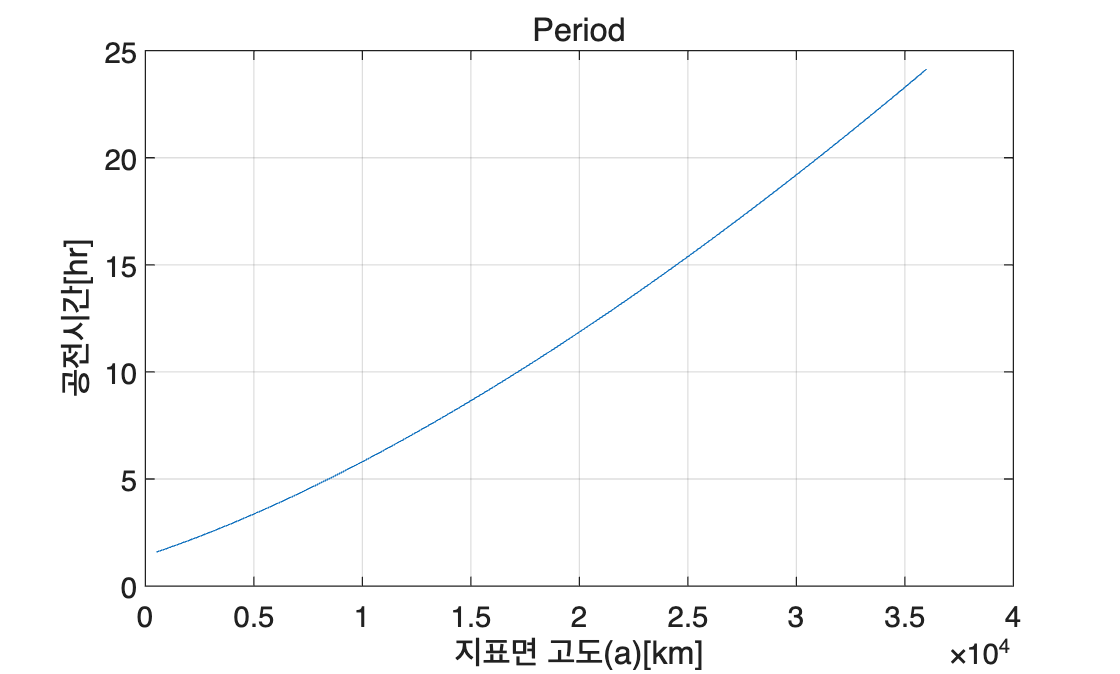


T = zeros(1,length(h));
V = zeros(1,length(h));

for i = 1:length(h)
    n = sqrt(mu/(h(i)+R)^3);
    T(i) = 2*pi/n/3600;
    V(i)= sqrt(2*mu/(h(i)+R));
end

figure;
plot(h, T);
title('Period');
xlabel('지표면 고도(a)[km]');
ylabel('공전시간[hr]');
grid on;

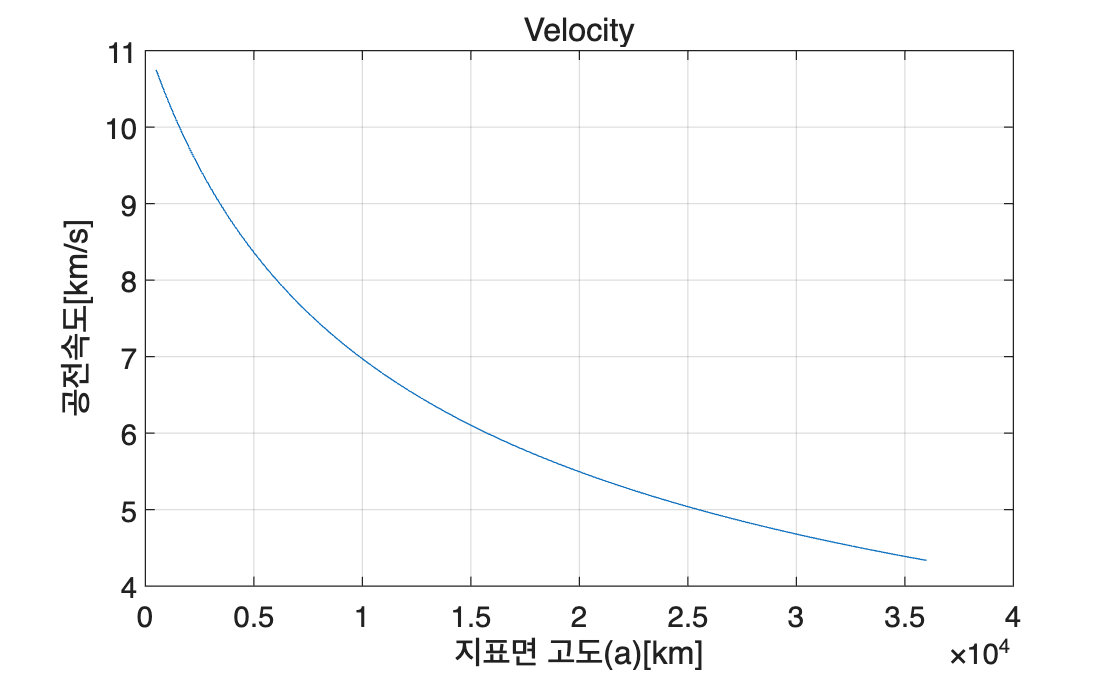

figure;
plot(h, V);
title('Velocity');
xlabel('지표면 고도(a)[km]');
ylabel('공전속도[km/s]');
grid on;

### 2. 궤도 변환 [20점]

2.1 궤도 6요소(케플러 요소)가 다음과 같이 주어졌다.


$$\alpha ={\left\lbrack \begin{array}{cccccc}
a & e & i & \Omega \; & \omega \; & f
\end{array}\right\rbrack }^{T\;} =\left\lbrack \begin{array}{cccccc}
7000\;\textrm{km} & 0\ldotp 001 & 97\ldotp 8^o  & {270}^o  & {90}^o  & {45}^o 
\end{array}\right\rbrack$$


직교좌표계(지구관성좌표계-ECI)에서의 위치, 속도로 변환하시오. 

% 아래에 코드를 작성하시오.
[r_eci, v_eci] = keplerian2ijk(7000*1e3, 0.001, 97.8, 270, 90, 45);
disp(r_eci/1e3); %km

   1.0e+03 *

  -0.671282470921283
   4.946244995180861
   4.900481547418125



disp(v_eci/1e3); %km/s

   0.724160396416412
   5.343414177627966
  -5.286499817490024



2.2 이번엔 반대로 ECI좌표계에서의 위치, 속도가 아래와 같이 주어졌다. 케플러 요소로 변환하시오. 


$$\mathit{\mathbf{r}}=\left\lbrack \begin{array}{ccc}
7639\ldotp 877 & 1330\ldotp 522 & -4997\ldotp 242
\end{array}\right\rbrack \;\;\textrm{km}$$
 


$$\mathit{\mathbf{v}}=\left\lbrack \begin{array}{ccc}
0\ldotp 411 & 5\ldotp 587 & 3\ldotp 277
\end{array}\right\rbrack \;\;\textrm{km}$$
 

% 아래에 코드를 작성하시오.
r_ijk = [7639.877, 1330.522, -4997.242] * 1e3;   % m
v_ijk = [0.411, 5.587, 3.277] * 1e3; %m/s

[a,e,i,RAAN,argp,nu] = ijk2keplerian(r_ijk,v_ijk);
disp([a,e,i,RAAN,argp,nu]); % m , - , deg, deg, deg, deg;

   1.0e+06 *

   8.999735526779137   0.000000100072907   0.000045002377403   0.000049995990854   0.000060013603857   0.000249989228761



### 3. 궤도전파 [30점]

3.1 위성의 초기 궤도가 아래 식과 같다. 위성의 공전주기를 구하고 1 공전주기 동안 궤도를 전파하시오. 3차원 그래프로 위성의 궤적을 지구와 함께 그리시오. 


$$\alpha ={\left\lbrack \begin{array}{cccccc}
a & e & i & \Omega \; & \omega \; & f
\end{array}\right\rbrack }^{T\;} =\left\lbrack \begin{array}{cccccc}
7000\;\textrm{km} & 0\ldotp 001 & 97\ldotp 8^o  & {270}^o  & {90}^o  & {45}^o 
\end{array}\right\rbrack$$


초기 시간은 2025-06-21 12:00:00 [KST] 으로 가정하시오.

% 아래에 코드를 작성하시오.
a = 7000; 
e = 0.001 ;
inc = 97.8;
Omega1 = 270;
w = 90;
f = 45;
n_1 = sqrt(mu/(a)^3);
T_1 = 2*pi/n_1;
startTime = datetime(2025,6,21,12,0,0);
stopTime = startTime + seconds(T_1);
sampleTime = 10;
sc = satelliteScenario(startTime, stopTime, sampleTime); 

sat = satellite(sc, a*1e3, e, inc, Omega1, w, f, 'OrbitPropagator', 'two-body-keplerian', 'Name', 'donghoon_hw3');

show(sat);


3-2. 같은 시간 동안 위성의 지상 궤적을 경도-위도 평면에 그리시오.

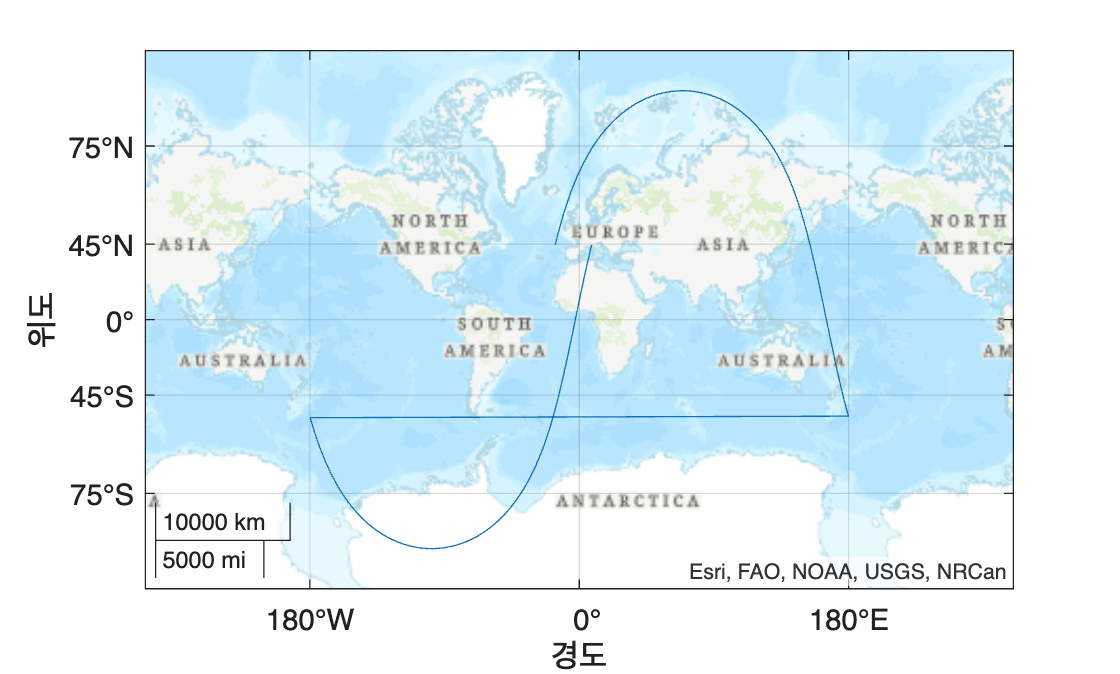

% 아래에 코드를 작성하시오.
[LLA, vel, timeout] = states(sat, 'CoordinateFrame', 'geographic');
figure;
geoplot(LLA(1,:), LLA(2,:));
geobasemap topographic

### 4. 위성 식 구간 [30점]

4.1 위성의 초기 궤도 및 전파 구간을 3번 문제와 동일하게 가정한다. 위성의 식 진입 시간, 탈출 시간, 구간 길이를 함께 구하시오.

% 아래에 코드를 작성하시오.
eclSat = eclipse(sat,IncludeLunarEclipse=true);
intvls = eclipseIntervals(eclSat); 
disp(intvls.StartTime); %진입시간

   2025-06-21 12:36:50



disp(intvls.EndTime); %탈출시간

   2025-06-21 13:12:10



disp(intvls.Duration); %구간길이

        2120



4.2 RAAN 값에 따른 식 구간 비율을 구해보자. 식 구간 비율[%]이란 $\frac{\textrm{eclipse}\;\textrm{period}}{\textrm{orbit}\;\textrm{period}}\times 100$ 을 나타낸다. RAAN이 270 도일 때와 180 도일 때의 식 구간 비율을 각각 구하시오.

% 아래에 코드를 작성하시오.
%270도일 때 식 비율
eclipse_rate_270 = intvls.Duration/T_1 *100;

Omega2 = 180;
n_2 = sqrt(mu/(a)^3);
T_2 = 2*pi/n_2;
startTime = datetime(2025,6,21,12,0,0);
stopTime = startTime + seconds(T_2);
sampleTime = 10;
sc_2 = satelliteScenario(startTime, stopTime, sampleTime); 

sat_180 = satellite(sc_2, a*1e3, e, inc, Omega2, w, f, 'OrbitPropagator', 'two-body-keplerian', 'Name', '180');
eclSat_180 = eclipse(sat_180, IncludeLunarEclipse=true);
intvls_180 = eclipseIntervals(eclSat_180); 

%180도일 때 식 비율
eclipse_rate_180 = intvls_180.Duration/T_2 *100;

disp(eclipse_rate_270);

  36.372870781759524



disp(eclipse_rate_180);

  20.759987568834447



4.3 RAAN 값이 180 도일 때 식 비율이 감소한 이유는 무엇일까? 궤도와 태양 기하로부터 설명하시오.

% 아래에 설명하시오.

4.3 설명 

RAAN은 궤도면의 공간적 방향을 결정하는 궤도요소로,  태양 방향 벡터에 대한 궤도면의 상대적인 기하를 변화시킨다.  이로 인해 궤도면과 태양 방향 사이의 각도인 Beta angle이 결정된다. Beta angle은 위성이 지구 그림자(Eclipse)를 통과하는 정도를 결정하는 핵심 기하학적 변수이다. Beta angle이 커질수록 태양은 궤도면으로부터 더 벗어난 위치에 존재하게 되며, 위성 궤적은 지구 그림자 원통을 깊게 통과하지 않고 얕게 스쳐 지나가게 된다. 이때 그림자 영역과의 교차 경로 길이(chord length)가 감소하게 되므로,  위성이 그림자 내부에 머무는 시간이 줄어들고 식 구간 비율이 감소한다.

따라서 RAAN이 180°일 경우에는 궤도면이 태양 방향에 대해 더 유리한  방향으로 배치되어 Beta angle이 증가하고, 그 결과 eclipse 구간이 감소하게 된다.